## LQR Controller

### State space model for the plant

% states:
%   x1 x2 x3 x4 x5
%   psi, delta_phi, psi_dot, delta_phi_dot, i_m

% psi: yaw angle
% delta_phi: pendulum angle (deviation from upright position)

A = [
    0 0 1 0 0;
    0 0 0 1 0;
    0 92.53 -3.603 -0.06574 252.2;
    0 211.0 -3.656 -0.1499 255.9;
    0 0 -36.21 0 -7241
    ];

B = [0; 0; 0; 0; 862.1];

C = [0 1 0 0 0];

D = 0;

sys = ss(A,B,C,D)

sys =
 
  A = 
             x1        x2        x3        x4        x5
   x1         0         0         1         0         0
   x2         0         0         0         1         0
   x3         0     92.53    -3.603  -0.06574     252.2
   x4         0       211    -3.656   -0.1499     255.9
   x5         0         0    -36.21         0     -7241
 
  B = 
          u1
   x1      0
   x2      0
   x3      0
   x4      0
   x5  862.1
 
  C = 
       x1  x2  x3  x4  x5
   y1   0   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



% % double checking the given G(s) and state space matrices agree

% figure(1); clf; hold on
% bode(C*inv(s*eye(5) - A)*B)
% [b,a] = ss2tf(A,B,C,D);
% bode(tf(b,a))
% bode(G)
% legend('via formula', 'via ss2tf', 'given')

### Design LQR controller

% https://au.mathworks.com/help/control/ref/lti.lqr.html
% https://staff.uz.zgora.pl/wpaszke/materialy/kss/lqrnotes.pdf
%   page 9/52

% ~~~ define state-cost weighted matrix using Bryson's rule

% no more than 5 degree movement in yaw
psi_max = deg2rad(5);

% no more than 5 degree deviation from upright
delta_phi_max = deg2rad(5);

% max yaw speed
psi_dot_max = deg2rad(360);

% max pitch speed
delta_phi_dot_max = deg2rad(2*360);

% max current: I = V_max/R = V_max/8.4
V_max = 15;
i_m_max = V_max/8.4;

Q = diag([1/psi_max^2, 1/delta_phi_max^2, 1/psi_dot_max^2, 1/delta_phi_dot_max^2, 1/i_m_max^2]);


% ~~~ define input-cost weighted matrix using Bryson's rule

R = V_max;


% ~~~ solve the system

[K,S,P] = lqr(sys,Q,R);

### Check the response

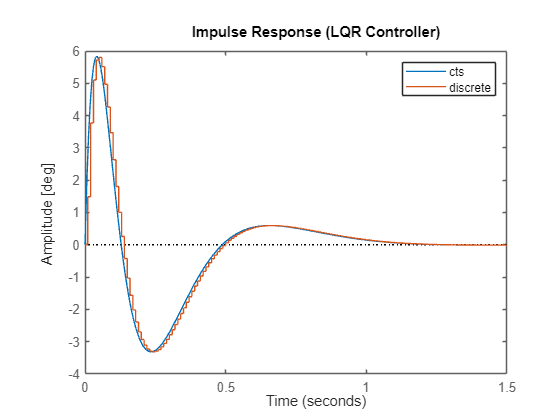

% cts system
sys_LQR = ss(A-B*K,B,C,D);

% discrete system
Ts = 1/100;
opts = c2dOptions('Method', 'zoh');
sys_LQR_discrete = c2d(sys_LQR, Ts, opts);

figure(1); clf; hold on
impulse_mag = 0.2;
impulse(impulse_mag * sys_LQR * 180/pi)
impulse(impulse_mag * sys_LQR_discrete * 180/pi)
ylabel("Amplitude [deg]")
title("Impulse Response (LQR Controller)")
legend('cts','discrete')